% EDIT THESE TO PLAY: 
% Set the seed to have repeatable control.
seed = 123;

% You can also add in simulation params here. 
% Param1 = exponent
% Param2 = semiSat
% Param3 = beta (keep this 1)
% Param4 = sigma (keep this .01, but you'll set noise below).
simulatedPsiParams = [];
%simulatedPsiParams = [.3162, .55, 1, .01];

% Allow Q+ to control the stimuli or not (false).
qpPres = false;

% Noise in standard deviations of maxBOLD
noiseSD = .1;

% Number of trials to run.
nTrials = 100;

% Initial baseline and max BOLD trials.
% Max BOLD trials are not necessary with maxBOLD locked, but at least 1
% baseline is required.
baselineMaxBOLDInitial = 1;


% The following options can be edited, but probably don't make much
% difference.

% Provide a model handle
model = @nakaRushton;

% Specify the parameter domain. Each value must correspond to a parameter
% expected by the model. 
paramsDomain = struct;
paramsDomain.exponent = makeDomain(-1,1,15,'spacing','log');
paramsDomain.semiSat = makeDomain(.1,1,15);

% We are locking in beta right now. 
paramsDomain.beta = makeDomain(.75,1.25,1,'spacing','zeno');

% Sigma in the parameter domain is searching for noiseSD
paramsDomain.sigma = makeDomain(0.01,1,20);

% Specify a stimulus domain and whether it spaced linear or log.
stimulusDomain = {makeDomain(.0001,1,31)};
stimulusDomainSpacing = 'lin';

% Set the number of outcome categories / bins.
nOutcomes = 21;

%How long the trials are (in seconds).
trialLength = 12;

% Do you want to see plots?
showPlots = true; 

% Again, important to lock in BOLD for the moment. 
% The range of BOLD signal to simulate (e.g., from baseline to maximum BOLD)
maxBOLDSimulated = 1.5;
maxBOLDInitialGuess = 1.5;

[myQpfmriParams,myQpParams] = qpfmriParams(model,paramsDomain,'qpPres',qpPres,...,
'stimulusDomain',stimulusDomain,'stimulusDomainSpacing',stimulusDomainSpacing,...,
'noiseSD',noiseSD,'nTrials',nTrials,'maxBOLDSimulated',maxBOLDSimulated,...,
'maxBOLDInitialGuess',maxBOLDInitialGuess,'seed',seed,...,
'baselineMaxBOLDInitial',baselineMaxBOLDInitial,...,
'trialLength',trialLength,'nOutcomes',nOutcomes,'simulatedPsiParams',simulatedPsiParams);


Initial random call 0.2751
Random call after seed 0.6965


Initializing Q+. This may take a minute...
Elapsed time is 0.712062 seconds.


Simulated parameters:
exponent: 2.933 semiSat: 0.304 beta: 1.000 sigma: 0.100 
Noise in the simulation is set at 0.300 relative to a maxBOLD of 1.50

Trial 1: baseline Stimulus Selection
Stimulus: 0.000
Output value 0.000

Q+ parameters
exponent: 0.517 semiSat: 0.100 beta: 1.000 sigma: 0.010 
maxBOLD estimate = 1.500




Trial 2: random Stimulus Selection
Stimulus: 0.467
Output value 1.412

Q+ parameters
exponent: 1.933 semiSat: 0.100 beta: 1.000 sigma: 0.010 
maxBOLD estimate = 1.500




Trial 3: random Stimulus Selection
Stimulus: 0.567
Output value 1.412

Q+ parameters
exponent: 3.726 semiSat: 0.293 beta: 1.000 sigma: 0.010 
maxBOLD estimate = 1.500




Trial 4: random Stimulus Selection
Stimulus: 0.533
Output value 1.588

Q+ parameters
exponent: 5.930 semiSat: 0.348 beta: 1.000 sigma: 0.048 
maxBOLD estimate = 1.500




Trial 5: maxBOLD Stimulus Selection
Stimulus: 1.000
Output value 1.588

Q+ parameters
exponent: 6.619 semiSat: 0.372 beta: 1.000 sigma: 0.049 
maxBOLD estimate = 1.500




Trial 6: random Stimulus Selection
Stimulus: 0.767
Output value 1.588

Q+ parameters
exponent: 6.849 semiSat: 0.362 beta: 1.000 sigma: 0.050 
maxBOLD estimate = 1.500




Trial 7: random Stimulus Selection
Stimulus: 0.833
Output value 1.059

Q+ parameters
exponent: 6.438 semiSat: 0.278 beta: 1.000 sigma: 0.122 
maxBOLD estimate = 1.500




Trial 8: random Stimulus Selection
Stimulus: 0.467
Output value 0.529

Q+ parameters
exponent: 9.986 semiSat: 0.437 beta: 1.000 sigma: 0.141 
maxBOLD estimate = 1.500



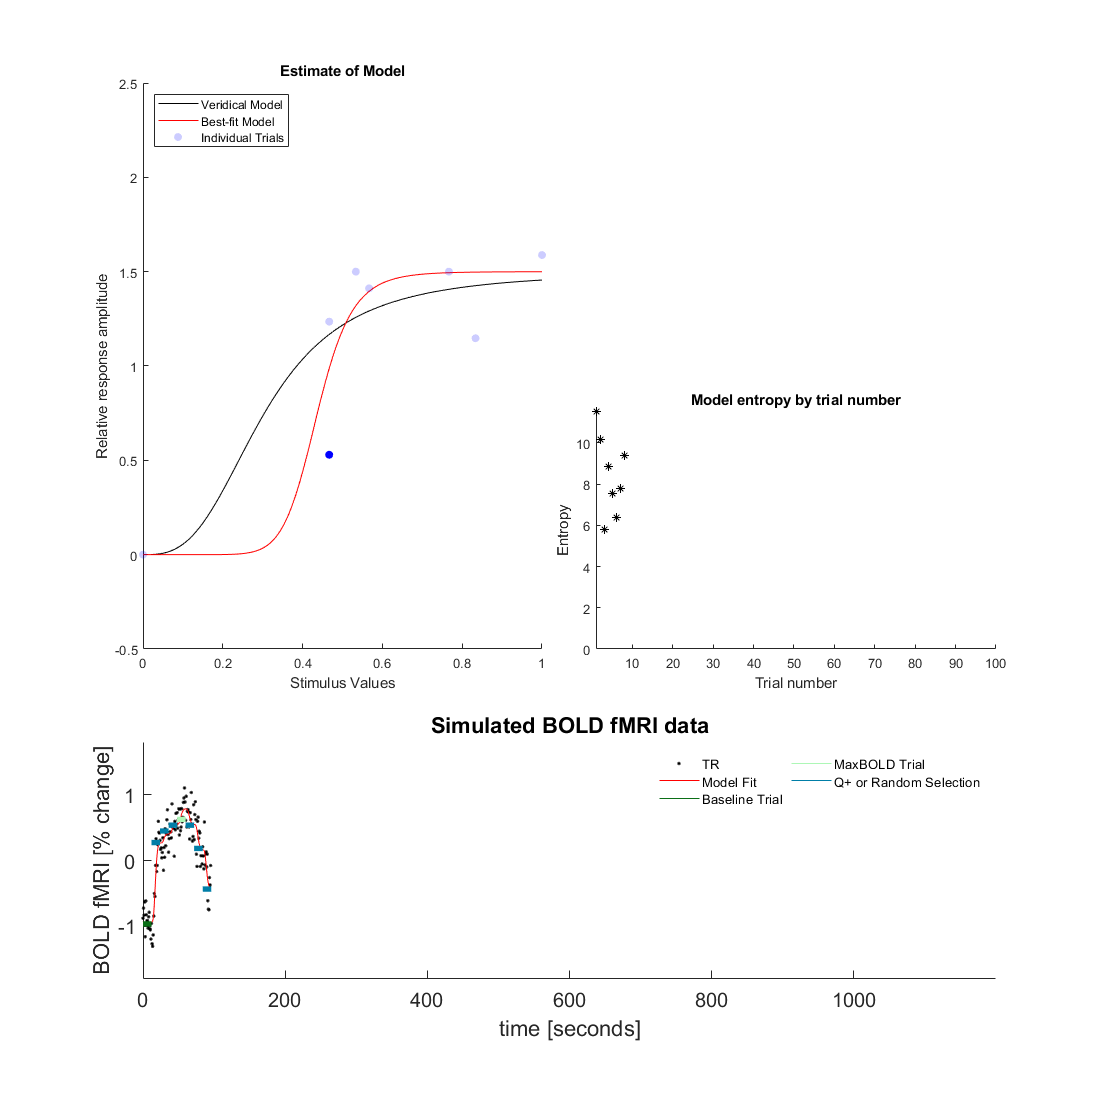



% Run the simulation. 
[qpfmriResults]=simulate(myQpfmriParams,myQpParams,'showPlots',showPlots);